clc
clear 
close all

fs = 1e2;
Ts = 1/fs;

T_start = -0.5;
T_end = 0.5;
t = T_start:Ts:T_end;
tau = 2*T_start:Ts:2*T_end;

theta_size = 1e5;
A = 10;
w0 = 5 * pi;

tau = 2*T_start:Ts:2*T_end;

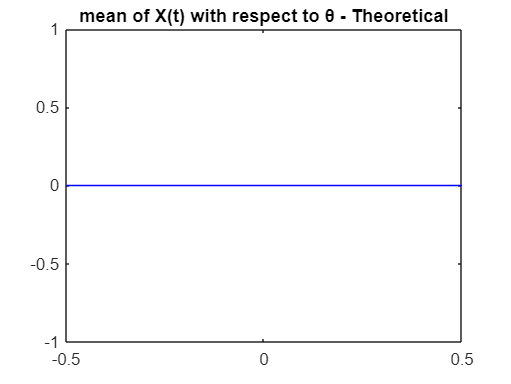

E_theoreticla = zeros(length(t));
figure, plot(t, E_theoreticla, 'b'),
title('mean of X(t) with respect to θ - Theoretical');

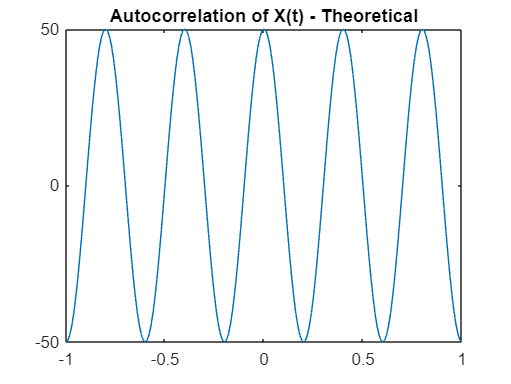


Rx_theoretical = (A^2/2)*cos(w0*tau);
figure, plot(tau, Rx_theoretical),
title('Autocorrelation of X(t) - Theoretical');

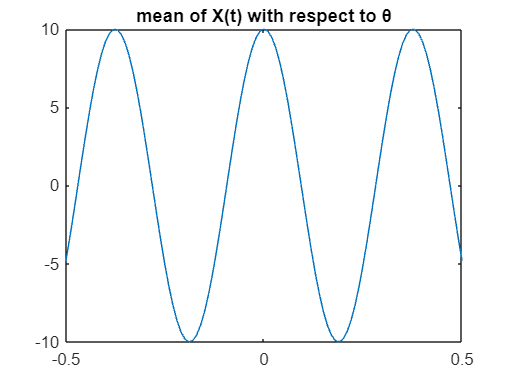

ts = repmat(t, theta_size, 1);
theta = 2*pi*rand(theta_size,length(t));

% theta = 2*pi*rand(theta_size,1);
% theta = repmat(t, theta_size, 1);

x = A*cos(w0*t + theta);

E_theta = mean(x);
figure, plot(t, E_theta),
ylim([-10,10]),
title("mean of X(t) with respect to θ");

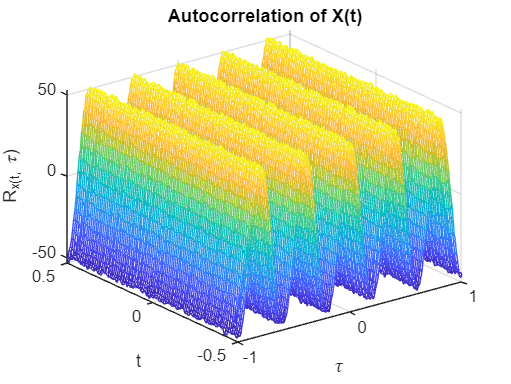

time = 4*T_start:Ts:4*T_end;

theta = 2*pi*rand(length(time), theta_size);
x = A*cos(w0*time + (2*theta)');
E_theta = mean(x);

R_x = zeros(length(t), length(tau));
for i=1:length(t)
    for j=1:length(tau)
        value = 2*((i-1)/100 - 0.5) + ((j-1)/100 - 1);
        index = (value+2)*100 + 1;s
        R_x(i,j) = E_theta(round(index));
        
    end
end

y = cos(w0*tau);
y = repmat(y, length(t), 1);
R_x = 50*(R_x + y);

figure, mesh(tau, t, R_x),
title("Autocorrelation of X(t)");
xlabel('𝜏');
ylabel('t');
zlabel('R_x(t, 𝜏)');

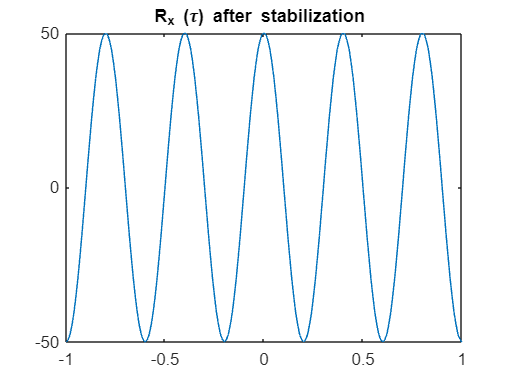


Stable_R_x = mean(R_x);
figure, plot(tau, Stable_R_x),
title("R_x (𝜏) after stabilization "),
ylim([-50,50]);